# Applications of Linear SSM

## Computation of linear frequency response function

% Vary random phases when generating sinusoidal forcing to obtain L0 with its confident interval 
sys = sys_Lorenz;
L0 = ssm2L(sys);
disp(L0);

    0.2101    0.4666         0
    0.1112    0.4644         0
         0         0   -0.0011



## Failure of the linear Markov assumption

sys = sys_diag_z; % Consider the linear SSM of variable z
[A_z, B_z, C_z, K_z, ~] = ssm2ABC(sys); % A_z is of real Jordan canonical form

% % Identify the modes
k = 1;
mode_ind = {};
while k <= length(A_z)
    if k < length(A_z) && A_z(k,k+1) ~= 0
        block_ind = [k, k+1];
        k = k + 2;
    else
        block_ind = k;
        k = k + 1;
    end
    mode_ind = [mode_ind,{block_ind}];
end

% % Statistcal properties of the modes (Table2 in the article)
eigen = []; % Eigenvalue
efold_time = NaN(1,length(mode_ind)); % e-folding time
inhe_fre = []; % Inherent frequency (for 2-dimensional modes)
trans_func = NaN(1,length(mode_ind)); % Transfer function
for k = 1:length(mode_ind)
    ind = mode_ind{k};
    A = A_z(ind,ind);
    B = B_z(ind,:);
    C = C_z(:,ind);
    efold_time(k) = -T / log(abs(max(eig(A))));
    trans_func(k) = ssm2L({A,B,C,NaN,NaN});
    if length(ind) == 2
        aux = eig(A);
        eigen = [eigen string(real(aux(1))) + "±" + string(imag(aux(1)))];

        theta = abs(angle(aux(1))); % Angle of the eigenvalue (consider positive value)
        % Find the minimum positive integral K, s.t. there exists an integral m with K*theta = 2m*pi approximately holding
        epsilon = 0.1/(2*pi); % Permitted error
        K = 1;
        m = K*theta / (2*pi);
        err = abs(m - round(m));
        while err > epsilon
            K = K + 1;
            m = K*theta / (2*pi);
            err = abs(m - round(m));
        end
        inhe_fre = [inhe_fre string(1/(K*T))];
    else
        eigen = [eigen string(eig(A))];
        inhe_fre = [inhe_fre "---"];
    end
end

fprintf("Eigenvalues of the modes are: " + join(eigen,", "));

Eigenvalues of the modes are: 0.86275±0.49284, 0.79256±0.5682, 0.6492±0.30516, 0.50525±0.84643, 0.35831±0.89933, 0.97161

fprintf("e-folding times of the modes are: " + join(string(efold_time), ", "));

e-folding times of the modes are: 9.7282, 2.4883, 0.18814, 4.3592, 1.9269, 2.1701

fprintf("Inherent frequencies of the modes are: " + join(inhe_fre,", "));

Inherent frequencies of the modes are: 1.3333, 1.6, 0.37209, 2.6667, 0.27586, ---

fprintf("Transfer function of the modes are: " + join(string(trans_func), ", "));

Transfer function of the modes are: 0.0065196, -0.0079649, 0.042862, 0.0006687, -0.00011778, -0.043025

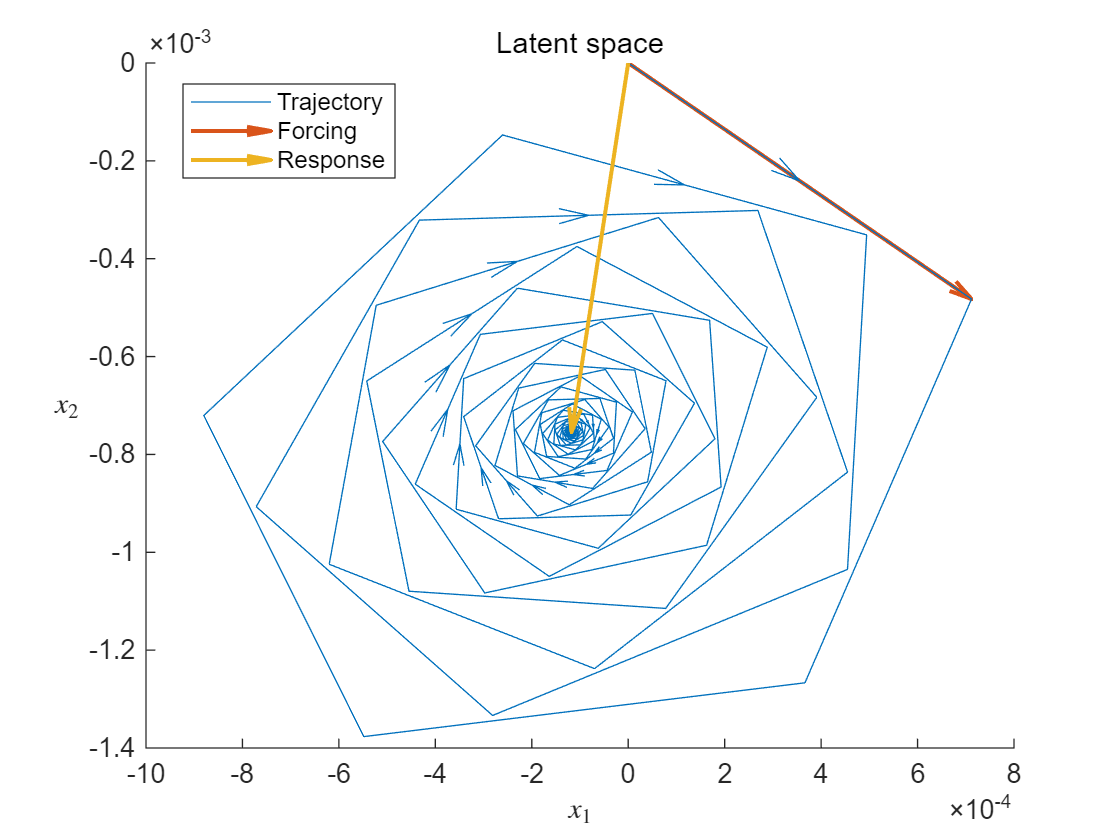

% % Visualization of a 2-dimensional mode

% Apply a variable tranformation such that C = [1 0]
A_z_1 = A_z;
B_z_1 = B_z;
C_z_1 = C_z;
K_z_1 = K_z;

for k = 1:length(mode_ind)
    block_ind = mode_ind{k};
    B = B_z(block_ind);
    C = C_z(block_ind);
    K = K_z(block_ind);
    if length(block_ind) == 2
        A = A_z(block_ind,block_ind);
        P = [1/C(1), -C(2)/C(1); 0, 1];
        A_z_1(block_ind,block_ind) = P^(-1) * A * P;
        B_z_1(block_ind) = P^(-1) * B;
        C_z_1(block_ind) = [1 0];
        K_z_1(block_ind) = P^(-1) * K;
    else
        B_z_1(block_ind) = C * B;
        C_z_1(block_ind) = 1;
        K_z_1(block_ind) = C * K;
    end
end

% Visualization
block_ind = [9 10];
A = A_z_1(block_ind, block_ind);
B = B_z_1(block_ind, :);
C = C_z_1(:, block_ind);
K = K_z_1(block_ind, :);

w = zeros(2,length(t1));
w0 = [0; 0]; % initial values of the latent variables
w(:,1) = w0;
fz = 1; % Forcing in the observed space
for k = 1:length(t1)-1
    w(:,k+1) = A*w(:,k) + B*fz;
end

f_lat = B*fz; % Forcing in the latent space
Delta_w = w(:,end); % Response in the latent space
out = C * Delta_w; % Response in the observed space

figure;
hold on;

forcing = quiver(0,0, f_lat(1),f_lat(2), 'off', 'lineWidth',1.5, 'Color',[0.85 0.33 0.10], 'DisplayName','Forcing'); % [0.93 0.49 0.19]
traj = plot(w(1,:),w(2,:), 'Color',[0 0.44 0.74], 'DisplayName','Trajectory');
idx = 1:5:(length(w)-1);
quiver(w(1,idx), w(2,idx), ...
       (w(1,idx+1)-w(1,idx))/2, (w(2,idx+1)-w(2,idx))/2, ...
       0, 'Color',[0 0.44 0.74] ,'HandleVisibility','off');
response = quiver(0,0, Delta_w(1),Delta_w(2), 'off', 'lineWidth',1.5, 'Color',[0.93 0.70 0.13], 'DisplayName','Response');

xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex','Rotation',0)
title('Latent space');
legend([traj, forcing, response], 'Location','best'); % 'Forcing','Response','Trajectory',
hold off;

exportgraphics(gcf, [filedir '\2d_latent.pdf'], 'ContentType', 'vector', 'BackgroundColor', 'none');

## Analysis of the frequency resonance

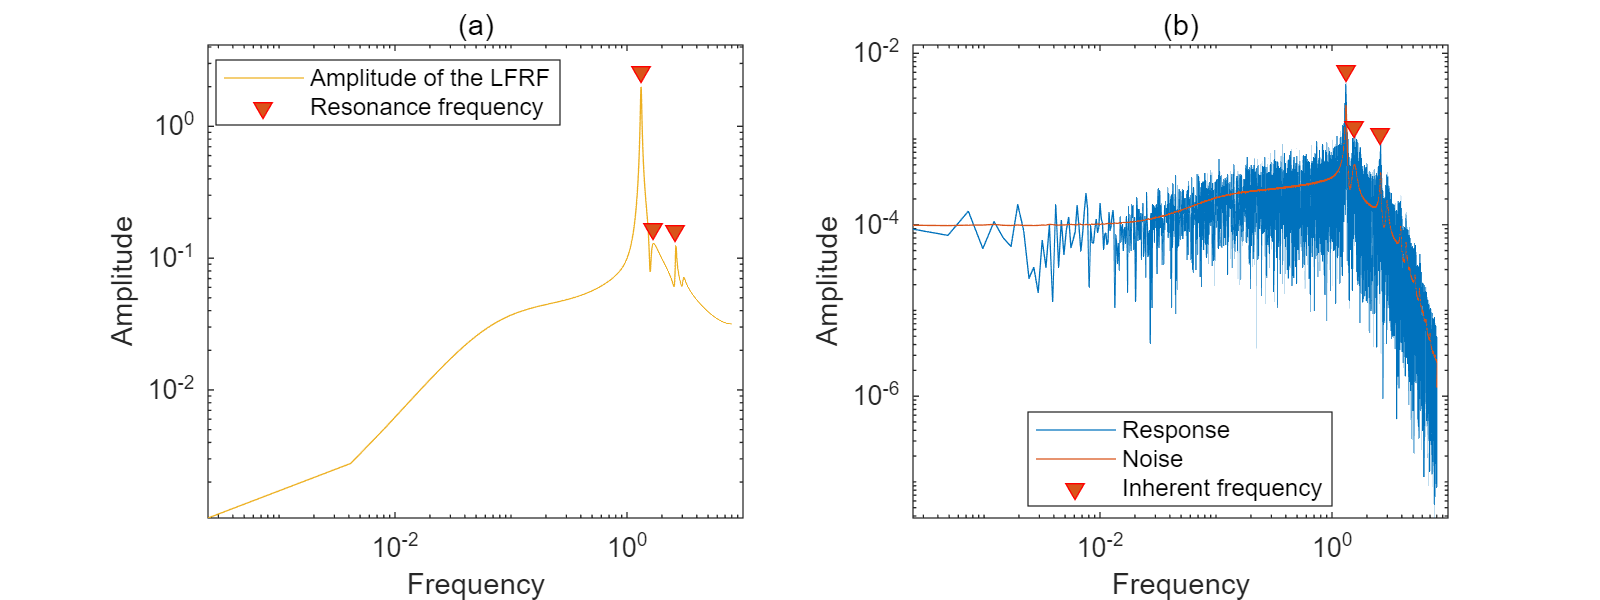

% % Peaks of the amplitude of the LFRF of variable z, which implies frequencie resonance phenomenon
Magnitude = zeros(1,length(fre)); % Amplitude of the LFRF of variable z

for k = 1:length(fre)
    nu = fre(k)/tg;
    Lnu = ssm2L(sys,nu);
    Magnitude(k) = abs(Lnu);
end

figure;
scnsize  = get(0,'ScreenSize'); 
len = 800;
wid = 300;
set(gcf,'Position', [scnsize(1,3)/2-len/2, scnsize(1,4)/2-wid/2,len, wid]);

subplot(1,2,1)
reson_ind = [339, 434, 677];
reson_fre = ((reson_ind - 1) * 16 + 1) / 4096;
posi = Magnitude(reson_ind) * 1.3;
loglog(Fs/N1*fre,Magnitude, 'Color',[0.93,0.69,0.13]);
hold on;
loglog(reson_fre(1), posi(1), 'rv', 'MarkerSize', 6, 'MarkerFaceColor',[0.85,0.33,0.1]);
loglog(reson_fre(2), posi(2), 'rv', 'MarkerSize', 6, 'MarkerFaceColor',[0.85,0.33,0.1]);
loglog(reson_fre(3), posi(3), 'rv', 'MarkerSize', 6, 'MarkerFaceColor',[0.85,0.33,0.1]);
xlim([0 10])
ylim([0 max(posi)*1.6])
xlabel("Frequency")
ylabel("Amplitude")
legend('Amplitude of the LFRF','Resonance frequency', 'Location','best')
title("(a)")
hold off;

subplot(1,2,2)
res_rest = p_rest_ba*sqrt(ng_rest/ng);
reson_ind = [5415, 6465, 10769];
reson_fre = (reson_ind - 1) / 4096;
posi = res_rest(3, reson_ind) * 1.3;
loglog(Fs/N1*(0:N1/2),res_rest(3,:), Fs/N1*(0:N1/2),noise(3,:))
hold on;
loglog(reson_fre(1), posi(1), 'rv', 'MarkerSize', 6, 'MarkerFaceColor',[0.85,0.33,0.1]);
loglog(reson_fre(2), posi(2), 'rv', 'MarkerSize', 6, 'MarkerFaceColor',[0.85,0.33,0.1]);
loglog(reson_fre(3), posi(3), 'rv', 'MarkerSize', 6, 'MarkerFaceColor',[0.85,0.33,0.1]);
xlim([0 10])
ylim([0 max(posi)*2])
xlabel("Frequency")
ylabel("Amplitude")
legend("Response","Noise",'Inherent frequency', 'Location','best')
title("(b)")

exportgraphics(gcf, [filedir '\resonance.pdf'], 'ContentType', 'vector', 'BackgroundColor', 'none');